# Actividad 2

## Velocidades lineales y angulares de un robot cartesiano de 3GDL

### Eleazar Olivas Gaspar A01731405

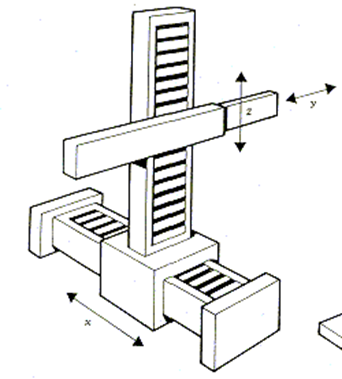

Figura 1: Diagrama del sistema que se busca modelar.

La configuración inicial que sse tomará para empezar la solución del proble es mober el marco de referencia inicial a nuestra conveniencia. A diferencia de la imagen anterior nuestro marco de referencia se girará con respecto a y 90° positivos, lo cuál hará que el eje x pase a ser z, el eje z será -x y el eje y se mantendrá igual.

A continuación se resolverá el problema:

El primer pasó será el limpear nuestro entorno de trabajo.

clear all
close all
clc

Posteriormente se inicializan las variables simbólicas.

syms t l1(t) l2(t) l3(t)

Se hace la configuracion de juntas del robot.

Donde 0 es rotacional, y 1 es prismatica, para este robot todas las juntas son prismaticas.

RP=[1 1 1]

RP =      1     1     1


Se inicializan las coordenadas articulares.

disp('Coordenadas generalizadas');

Coordenadas generalizadas


Q= [l1 l2 l3]

$$Q(t) = \left(\begin{array}{ccc} l_{1}\left(t\right) & l_{2}\left(t\right) & l_{3}\left(t\right) \end{array}\right)$$

Se inician las velocidades generalizadas

disp('Velocidades generalizadas');

Velocidades generalizadas


Qp= diff(Q, t)

$$Qp(t) = \left(\begin{array}{ccc} \frac{\partial }{\partial t}l_{1}\left(t\right) & \frac{\partial }{\partial t}l_{2}\left(t\right) & \frac{\partial }{\partial t}l_{3}\left(t\right) \end{array}\right)$$

Se añaden los grados de libertad del robot.

GDL= size(RP,2)

GDL = 3

GDL_str= num2str(GDL)

GDL_str = '3'

 Posteriormente se hace el cambio más significativo con respecto a las actividades anteriores

#### Junta 1

%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [0 0 -1;
           0 1 0;
           1 0 0];

Para la primera junta se toma el movimiento de l1 en z para representar el movimiento de junta, a la cuál posteriormente se le hace una rotacion  de 90° negativos sobre el eje de y con el fin de dejar el marco de referencia aliniado con la siguiente junta.

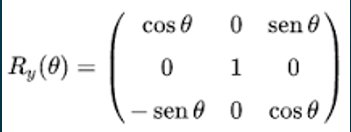

Figura 2: Matris de rotación en y.

con el fin de obtener la matriz de rotacion anterior se evalua la matriz de la figura 2 en -90° dando como resultado nuestra primera pagina de nuestras matrices de rotación.

#### Junta 2

%Junta 2
%Posición de la junta 2 respecto a 0
P(:,:,2)= [0;l3;l2];
%Matriz de rotación de la junta 2 respecto a 0
R(:,:,2)= [1  0 0;
           0  0 1;
           0 -1 0];

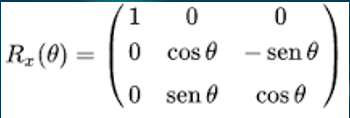

Figura 3: Matriz de rotacion sobre x.

De la misma manera que la matriz anterior, sobre esta matriz se meten los mobimientos de l2 sobre el eje z, y además se mete el movimiento ed l3 sobre la misma matriz de; pero sobre el eje y.

y final mente se evalua la matriz de rotación de de la figura 3 en -90° con el fin de alinear el eje z con el último movimiento.

%Junta 3
%Posición de la junta 3 respecto a 0
P(:,:,3)= [0; 0; 0];
%Matriz de rotación de la junta 3 respecto a 0
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];

Para finalizar el analisis de juntas, se añade la tercera junta en la cual no hay movimiento, ni rotacion del marco de referencia, por lo que solo se multiplica por la matriz dentidad.

#### Análisis de velocidades.

Posteriormente para continuar con el análisis de velocidades se sigue el mismo procedimiento de la actividad anterior, debido a que los cambios echo se hacen con el fin de porder reulizar ese mismo código.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1])

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i))
    

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i)
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


$$\left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T1


$$\left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ l_{1}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Matriz de Transformación local A2


$$\left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 0 & -1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T2


$$\left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & -l_{2}\left(t\right)\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ l_{1}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} -l_{2}\left(t\right)\\ l_{3}\left(t\right)\\ l_{1}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Matriz de Transformación local A3


$$\left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 0 & -1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T3


$$\left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & -l_{2}\left(t\right)\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & -l_{2}\left(t\right)\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ l_{1}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} -l_{2}\left(t\right)\\ l_{3}\left(t\right)\\ l_{1}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} -l_{2}\left(t\right)\\ l_{3}\left(t\right)\\ l_{1}\left(t\right) \end{array}\right)$$

 En el paso anterior se hace la inicializacion de el vector de ceros con el fin de poder realizar las matrices homogeneas locales y globales.

%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1 , th2 y th3
Jv11= functionalDerivative(PO(1,1,GDL), l1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
%Derivadas parciales de y respecto a th1 , th2 y th3
Jv21= functionalDerivative(PO(2,1,GDL), l1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
%Derivadas parciales de z respecto a th1 , th2 y th3
Jv31= functionalDerivative(PO(3,1,GDL), l1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33])

$$jv\_d(t) = \left(\begin{array}{ccc} 0 & -1 & 0\\ 0 & 0 & 1\\ 1 & 0 & 0 \end{array}\right)$$

Posteriormente se obtiene el jacobiano de forma diferencial, en este paso se tiene que cambiar la derivacion con respecto a theta con dericavion respecto a ln para cada una de las juntas.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
end    

disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


Jv_a= simplify (Jv_a)

$$Jv\_a = \left(\begin{array}{ccc} 0 & -1 & 0\\ 0 & 0 & 1\\ 1 & 0 & 0 \end{array}\right)$$

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


Jw_a= simplify (Jw_a)

$$Jw\_a = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

 Con este paso se saca el jacobiano de forma analítica de la misma forma que en la actividad 1.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp')

$$V(t) = \left(\begin{array}{c} -\bar{\frac{\partial }{\partial t}l_{2}\left(t\right)}\\ \bar{\frac{\partial }{\partial t}l_{3}\left(t\right)}\\ \bar{\frac{\partial }{\partial t}l_{1}\left(t\right)} \end{array}\right)$$

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp')

$$W(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Se finaliza mostrando los resultados que se obtuvieron para las velocidades lineales y angulares.

#### Resultados

    Velocidad lineal:

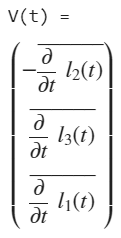

Figura 4: Resultados de la velocidad lineal

    Velocidad angular:

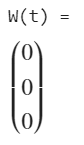

Figura 5: Resultados de la velocidad angular

Con los resultados obtenido podemos ver en en efecto son racionales con lo que se esperaba, debido a que no hay velocidad angular, esto es debido a que el movimiento que se modela es solo translacional, pero por otro lado se ve el movimiento en las velocidades lineales, además de que debido a que al hacer las configuraciones del marco de referencia el movimiento de l2 se encuntra en el lado negativo de x, dandonos una velocidad negativa dependiento a delta l2. mientras que en los otros movimiento concuerdan con nuestros cambios en el marco de referencia.